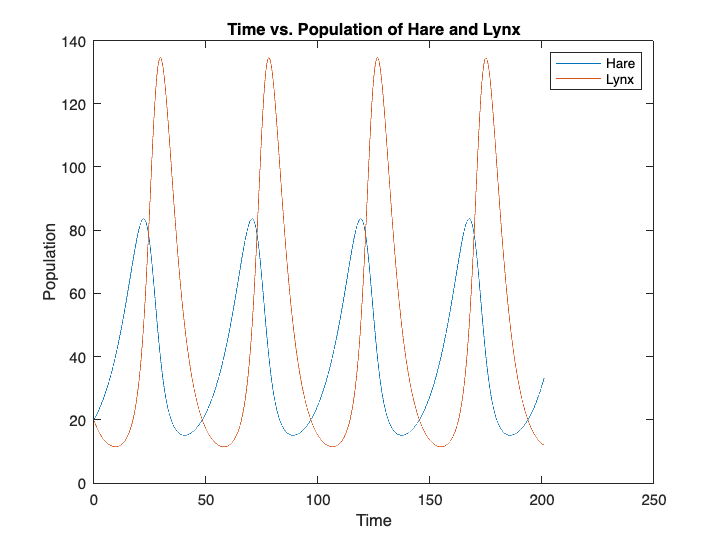

alpha = 0.1;
beta = 0.002;
gamma = 0.2;
delta = 0.005;

dt = 201 / 10000;
t = 0:dt:201;
sol = NaN(2, length(t));
sol(1, 1) = 20;
sol(2, 1) = 20;
for n = 2:length(t)
    A = [alpha, -beta * sol(1, n - 1); delta * sol(2, n - 1), -gamma];
    sol(:, n) = sol(:, n - 1) + dt * A * sol(:, n - 1);
    sol(:, n) = sol(:, n - 1) + (dt / 2) * A * (sol(:, n - 1) + sol(:, n));
end

H = sol(1, :);
L = sol(2, :);

figure;
plot(t, H, "DisplayName", "Hare")
hold on
plot(t, L, "DisplayName", "Lynx")
legend show
xlabel("Time")
ylabel("Population")
title("Time vs. Population of Hare and Lynx")